**ASSERVISSEMENT DANS LE DOMAINE CONTIINU**

**1) Fonction de transfert G(p) :**

Constantes : 

L = 2e-3

L = 0.0020

R = 1

R = 1

Ubatt = 24

Ubatt = 24

Formules : 

Tg =L/R

Tg = 0.0020

K = 1/R

K = 1

G(p) : 

G=tf([2*K*Ubatt],[Tg 1])

G =
 
      48
  -----------
  0.002 s + 1
 
Continuous-time transfer function.



**2) Fonction de transfert F(p) :  **

Constantes :

S  = 0.1041

S = 0.1041

R8 = 10e3

R8 = 10000

R5 = 5.1e3

R5 = 5100

R12 = 10e3

R12 = 10000

R21 = 220

R21 = 220

R18 = 12e3

R18 = 12000

C2 = 22e-9

C2 = 2.2000e-08

C7 = 22e-9

C7 = 2.2000e-08

Formules : 

Kfiltre = (R8/(R5+R8)) * (1 + R18/R12)

Kfiltre = 1.4570

Tr1 = (R8 * R5 / ( R8 + R5)) * C2

Tr1 = 7.4305e-05

Tr2 = R21 * C7

Tr2 = 4.8400e-06

F(p) : 

F=tf([Kfiltre*S],[Tr1*Tr2 Tr1+Tr2 1])

F =
 
              0.1517
  -------------------------------
  3.596e-10 s^2 + 7.914e-05 s + 1
 
Continuous-time transfer function.



**3) Fonction de transfert C(p) : **

Constantes : 

ft = 400

ft = 400

Formules : 

Tc3 = Tg

Tc3 = 0.0020

Tc4 = Ubatt*K*Kfiltre*S /(pi*ft)

Tc4 = 0.0029

C(p) : 

C=tf([Tc3 1],[Tc4 0])

C =
 
  0.002 s + 1
  -----------
  0.002897 s
 
Continuous-time transfer function.



**4) Fonction de transfert en boucle ouverte HBO : **

HBO = C*G*F

HBO =
 
                       0.01456 s + 7.28
  ----------------------------------------------------------
  2.083e-15 s^4 + 4.596e-10 s^3 + 6.023e-06 s^2 + 0.002897 s
 
Continuous-time transfer function.



Diagramme de bode : 

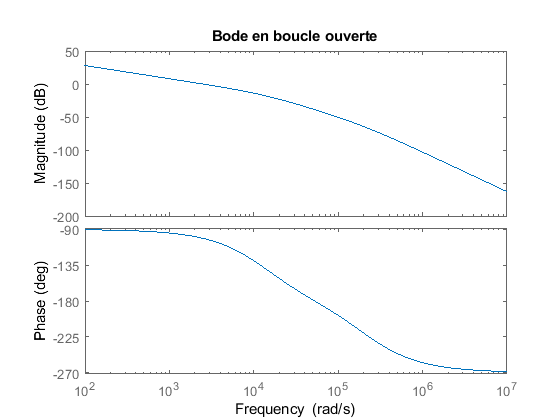

bode(HBO)
title("Bode en boucle ouverte")

On trouve une fréquence de transition égale à **400 HZ** et une marge de phase de **78 degrés**. 

**5) Fonction de transfert en boucle fermée HBF : **

HBF = HBO / ( 1 + HBO)

HBF =
 
                                                                                             
                    3.034e-17 s^5 + 6.706e-12 s^4 + 9.104e-08 s^3 + 8.602e-05 s^2 + 0.02109 s
                                                                                             
  --------------------------------------------------------------------------------------------------------------
                                                                                                                
  4.341e-30 s^8 + 1.915e-24 s^7 + 2.363e-19 s^6 + 5.578e-15 s^5 + 4.564e-11 s^4 + 1.259e-07 s^3 + 9.441e-05 s^2 
                                                                                                                
                                                                                                     + 0.02109 s
                                                                                                                
 
Continuous-time transfer funct

Diagramme de bode : 

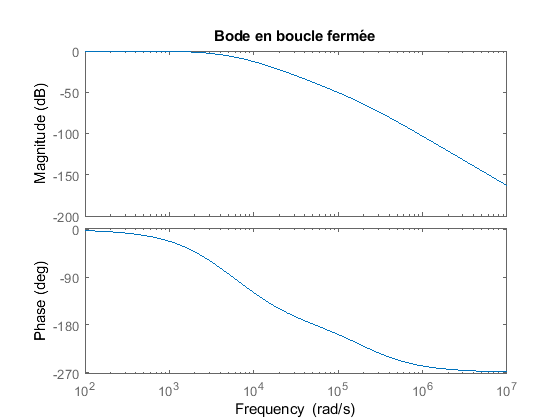

bode(HBF)
title("Bode en boucle fermée")

**6) Erreur statique **

out=sim("simtd1.slx")

out =   Simulink.SimulationOutput:

                      I: [1x1 timeseries] 
                   Iref: [1x1 timeseries] 
               consigne: [1x1 timeseries] 
              dutycycle: [1x1 timeseries] 
                 erreur: [1x1 timeseries] 
                 retour: [1x1 timeseries] 
                   tout: [560762x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


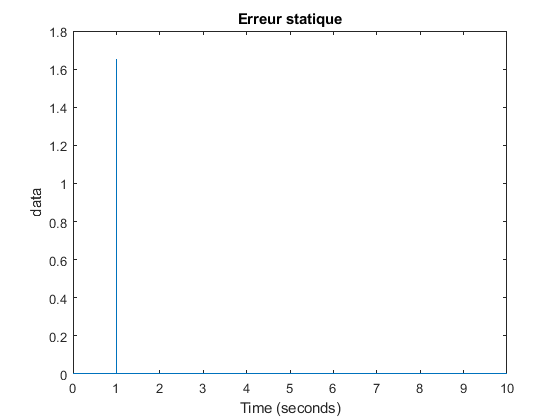

plot(out.erreur)
title("Erreur statique")

On trouve une erreur statique qui est nulle. 

**6) Rapport cyclique**

On va regarder le comportement du rapport cyclique :

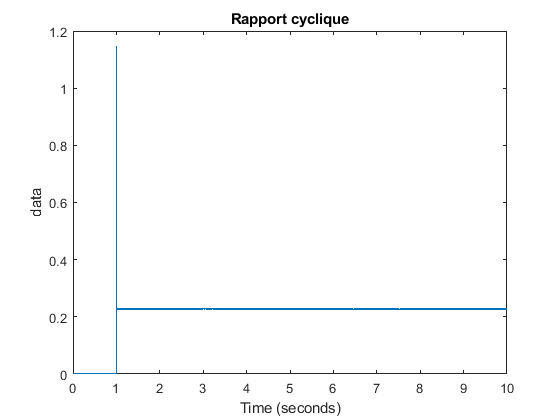

plot(out.dutycycle)
title("Rapport cyclique") 

On trouve un rapport cyclique supérieur à 0.5, donc il faut ajouter un saturateur

out=sim("saturateur")

out =   Simulink.SimulationOutput:

                      I: [1x1 timeseries] 
                   Iref: [1x1 timeseries] 
               consigne: [1x1 timeseries] 
              dutycycle: [1x1 timeseries] 
                 erreur: [1x1 timeseries] 
                 retour: [1x1 timeseries] 
                   tout: [560763x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


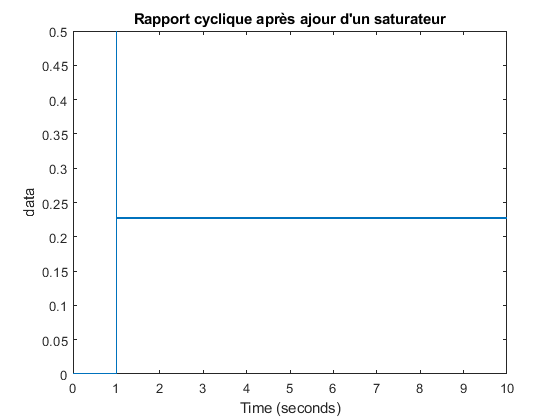

plot(out.dutycycle)
title("Rapport cyclique après ajour d'un saturateur") 

Finalement, notre rapport cyclique varie entre** -0.5 et + 0.5** . 

**ASSERVISSEMENT DANS LE DOMAINE DISCRET**

Maintenant, on va passer au domaine discret :

Formules :  

Te= 1/(6*ft)

Te = 4.1667e-04

z= tf ('z',Te)

z =
 
  z
 
Sample time: 0.00041667 seconds
Discrete-time transfer function.



Z1=(Te + 2*Tc3)

Z1 = 0.0044

Z0=(Te -2*Tc3)

Z0 = -0.0036

Z11=2*Tc4

Z11 = 0.0058

Z00=- 2*Tc4

Z00 = -0.0058

C(z) : 

Cz = (z*(Te + 2*Tc3)+(Te -2*Tc3)) / ( z*2*Tc4 - 2*Tc4)

Cz =
 
  0.004417 z - 0.003583
  ---------------------
  0.005793 z - 0.005793
 
Sample time: 0.00041667 seconds
Discrete-time transfer function.



On simule l'erreur dans le domaine discret: 

out=sim("discret")

out =   Simulink.SimulationOutput:

                      I: [1x1 timeseries] 
                   Iref: [1x1 timeseries] 
               consigne: [1x1 timeseries] 
              dutycycle: [1x1 timeseries] 
                 erreur: [1x1 timeseries] 
                 retour: [1x1 timeseries] 
                   tout: [1276x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


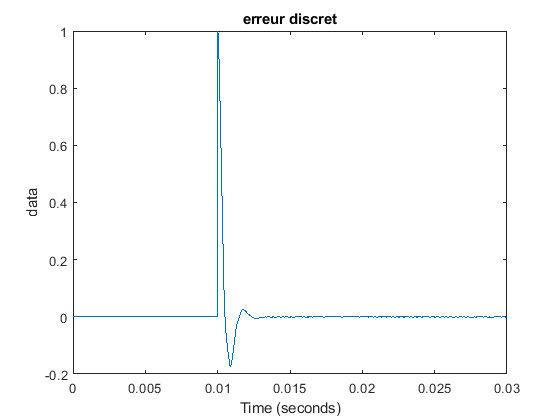

plot(out.erreur)
title("erreur discret")

Pente à comparer avec la pente sur keil : 

out=sim("validation")

out =   Simulink.SimulationOutput:

                 erreur: [1x1 timeseries] 
                 sortie: [1x1 timeseries] 
                   tout: [1203x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


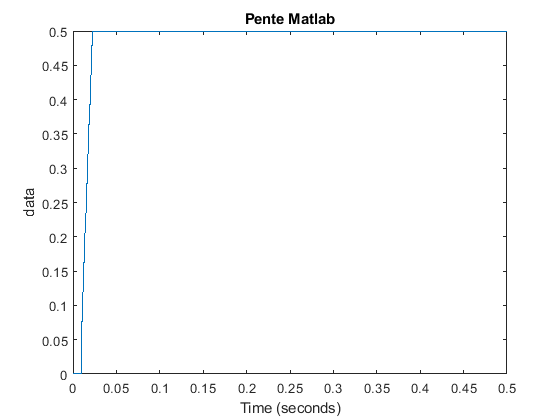

plot(out.sortie)
title("Pente Matlab")